## Lab 14_Sep_2023

### Reset

clc % Clear Command Window
clear all % Remove all items form the workspace

### Variable_Case sensitive

% Variables are case sensitive 
x = 2; fprintf('Variable x ='),disp(x)

Variable x =     2



X = [1;2]; fprintf('Matrix X = \n'), disp(X)

Matrix X = 
     1
     2



class_x = class(x); fprintf('Class of x is '),disp(class_x)

Class of x is double


### Operators

chk_temp = x < 40

chk_temp = logical
   1


        % Relational Operators
... <=, >=, ==, ~ =
    
    ... Logical Operators
... 0 False,  1 True
    
    ... Conditional Operators 
... ~ Not , & and, | or 

### If ...elseif ... else 

if (x >=10)
    x = x + 1;
    fprintf('x is greater than or equal to 10'), disp(x)
end


if (x >=10)
    x = x + 1;
    fprintf('x is greater than or equal to 10.   x  ='), disp(x)
else 
    x = x - 1;
    fprintf('x is not greater than or equal to 10.  x  ='),disp(x)
end

x is not greater than or equal to 10.  x  =     1




if (x >=10)
    x = x + 1;
    fprintf('x is greater than or equal to 10.   x  ='), disp(x)
elseif (x >= 20)
    x = x - 1;
    fprintf('x is greater than or equal to 20.  x  ='),disp(x)
else
    x
    fprintf('x is neither >= 10 nor >= 20,\n  x ='),disp(x)
end

x = 1

x is neither >= 10 nor >= 20,
  x =     1



### Matrics Operations

y = [12, 10, -3] % row matrix

y =     12    10    -3


z = [12; 10; -3] % column matrix

z =     12
    10
    -3


Y = [1, 2, 3; 4, 5, 6; 7, 8, 9] % square matrix

Y =      1     2     3
     4     5     6
     7     8     9


#### Slicing

Y33 = Y(3, 1:3), Y122 = Y(1:2, 2) 

Y33 =      7     8     9


Y122 =      2
     5


siz_Y33 = size(Y33), siz_Y122 = size(Y122)

siz_Y33 =      1     3


siz_Y122 =      2     1


#### Concatination

A = [1, 2; 3, 4]

A =      1     2
     3     4


a_cat = [A, 2*A; 3*A, 4*A], siz_acat = size(a_cat)

a_cat =      1     2     2     4
     3     4     6     8
     3     6     4     8
     9    12    12    16


siz_acat =      4     4


A = [0 1 2;
    1 0 -1;
    2 -1 0];

disp('Matrix A='), disp(A)

Matrix A=
     0     1     2
     1     0    -1
     2    -1     0



#### Augmented form    

A x = b

    [A, b]

A = [1, 3; 5, 4]

A =      1     3
     5     4


b = [1; 5]

b =      1
     5



aug = [A, b]

aug =      1     3     1
     5     4     5


#### Solution for the system of equations 

x = inv(A)*b %inverse of Matrix -> inv(A)

x =     1.0000
   -0.0000


OR

x = A\b

x =     1.0000
   -0.0000


#### matrix multiplication operation criteria

x = A*b % M-1 num of colums = M2 num of rows

x =     16
    25


#### Row vector to diagonal matrix

s = [1 3 5 6]

s =      1     3     5     6


Mtx_s = diag(s) 

Mtx_s =      1     0     0     0
     0     3     0     0
     0     0     5     0
     0     0     0     6


### Diagonal matrix to column vector

dg_Mtx_s = diag(Mtx_s), 

dg_Mtx_s =      1
     3
     5
     6


len_dg_Mtx_s = length(dg_Mtx_s), len_Mtx_s = length(Mtx_s)

len_dg_Mtx_s = 4

len_Mtx_s = 4

### Built-in funcitons

- zeros             ones            eye                rand

- diag               size             rank               length

- det                 inv

zer = zeros(3,3), ons = ones(2), ey = eye(3), rnd = rand % range between [0, 1]

zer =      0     0     0
     0     0     0
     0     0     0


ons =      1     1
     1     1


ey =      1     0     0
     0     1     0
     0     0     1


rnd = 0.9649

dig_ons = diag(ons), siz_dig = size(dig_ons), rnk_dig = rank(dig_ons)

dig_ons =      1
     1


siz_dig =      2     1


rnk_dig = 1

len_dig = length(dig_ons), dt_ey = det(ey), in_dig = inv(eye) 

len_dig = 2

dt_ey = 1

in_dig = 1

### Other built-in functions

- abs            sin            cos            acos

- deg2rad     exp           log            log10

- round         ceil            floor

ab = abs(-3) , sn30 = sin(30) , cs45 = cos(45), acs = acos(45)

ab = 3

sn30 = -0.9880

cs45 = 0.5253

acs = 0.0000 + 4.4997i

deg2rad(cs45)

ans = 0.0092

ex = exp(30), lg = log(30), log_10 = log10(30)

ex = 1.0686e+13

lg = 3.4012

log_10 = 1.4771

rund_off = round(log_10), cil_log_10 = ceil(log_10), flr_log10 = floor(log_10)

rund_off = 1

cil_log_10 = 2

flr_log10 = 1

### Eigen values and eigen vectors


$$A\;v\;=\;\;\lambda \;v$$



$$\begin{array}{l}
A=\textrm{matrix}\\
v=\textrm{eigen}\;\textrm{vector}\;\\
\lambda =\textrm{eigen}\;\textrm{value}
\end{array}$$



$$\left(A-\lambda \;I\right)v\;=\;0$$
            
$$\textrm{det}\left(A-\lambda \;I\right)=0$$


eigen vector staying on its on span during the linear transfermation

% determinent & inverse argument* must be square
eg_A = eig(A);
disp('Eigenvalues in column instead of diagonal'); disp(eg_A)

Eigenvalues in column instead of diagonal
   -1.6533
    6.6533



# Lab 21_Sep_2023

### Ploting Method 1

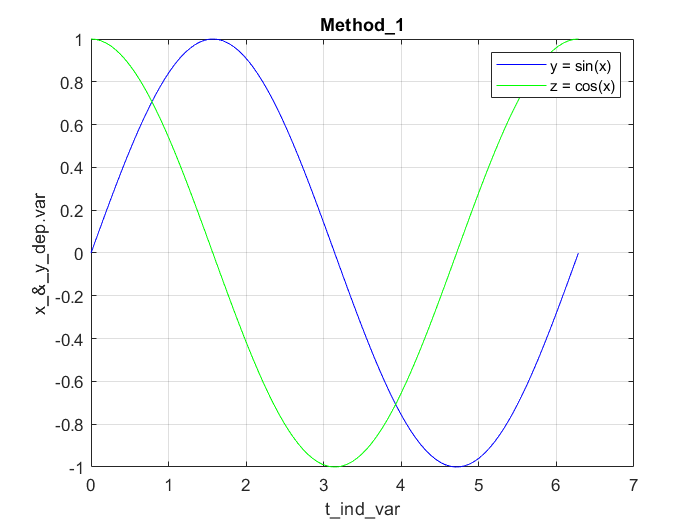

clc, clear all
x = linspace(0, 2*pi, 100);
% x = 0:0.01:2*pi;

y = sin(x);
z = cos(x);

plot(x, y, 'b')
hold on
plot(x, z, 'g')

title Method\_1
xlabel t\_ind\_var
ylabel x\_&\_y\_dep.var
legend('y = sin(x)', 'z = cos(x)')
grid on

hold off

### Ploting Method 2 

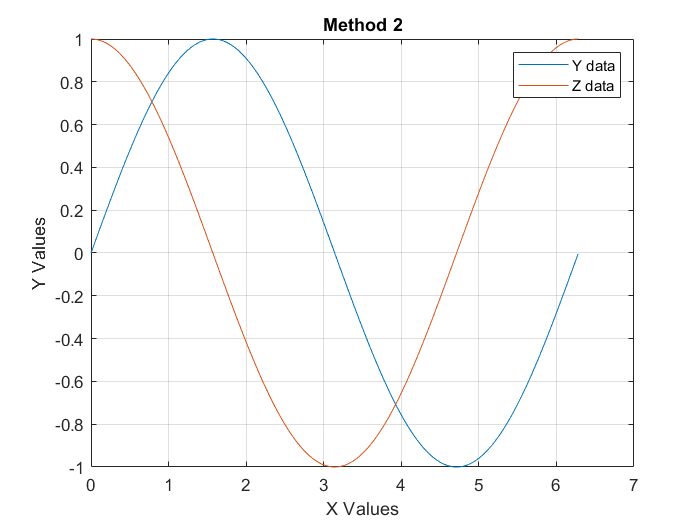

x = 0:0.01:2*pi;
y = sin(x);
z = cos(x);

figure 
plot(x,y,x,z);

xlabel 'X Values';
ylabel 'Y Values';
title 'Method 2';
legend ('Y data','Z data');
grid on

### Piecewise function


$$\begin{array}{l}
\left\lbrace y\;,0\le t\le 1\right\rbrace \\
\left\lbrace \frac{1}{t}\;,1\le t\le 6\right\rbrace 
\end{array}$$


### Piecewise plot method 1

clear all, close all
t1 = linspace(0, 1, 10) % from 0 to 1 with linearly spaced vector with 10 points 

t1 =          0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000


% t1 = 0:0.1:1 % 0 with increment 0.1 to 1

t2 = linspace(1, 6, 60) % from 1 to 6 with linearly spaced vector with 60 points

t2 =     1.0000    1.0847    1.1695    1.2542    1.3390    1.4237    1.5085    1.5932    1.6780    1.7627    1.8475    1.9322    2.0169    2.1017    2.1864    2.2712    2.3559    2.4407    2.5254    2.6102    2.6949    2.7797    2.8644    2.9492    3.0339    3.1186    3.2034    3.2881    3.3729    3.4576    3.5424    3.6271    3.7119    3.7966    3.8814    3.9661    4.0508    4.1356    4.2203    4.3051    4.3898    4.4746    4.5593    4.6441    4.7288    4.8136    4.8983    4.9831    5.0678    5.1525


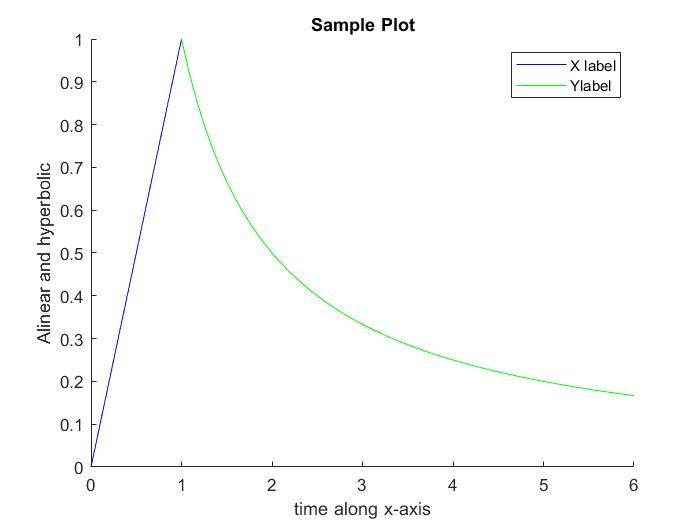

% t2 = 1:0.0847:6 % form 1 with increment of 0.0847 to 6

y = t1;
z = 1./t2;
hold on
plot(t1,y,'b')
plot(t2,z,'g')

% Sr typed it without prenthesis 
xlabel 'time along x-axis'
ylabel('Alinear and hyperbolic')
title 'Sample Plot'
legend('X label','Ylabel')
hold off

### Piecewise plot method 2

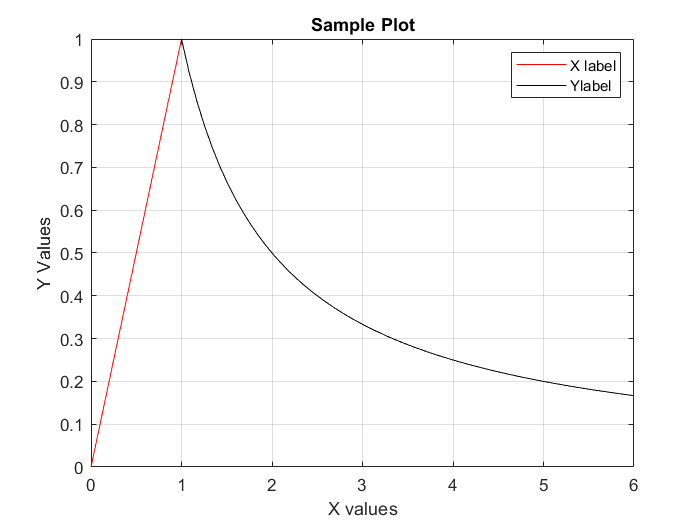

t1=linspace(0,1,10);
t2=linspace(1,6,60);
y=t1;
z=1./t2;
plot(t1,y,'r',t2,z,'k');
xlabel 'X values';
ylabel 'Y Values';
title 'Sample Plot'
legend('X label','Ylabel')
grid on

### Subploting 

% Syntax:
% subplot(rows, columns, index)
clear all, close all
t = 0:0.1:1;
y = cos(t)

y =     1.0000    0.9950    0.9801    0.9553    0.9211    0.8776    0.8253    0.7648    0.6967    0.6216    0.5403


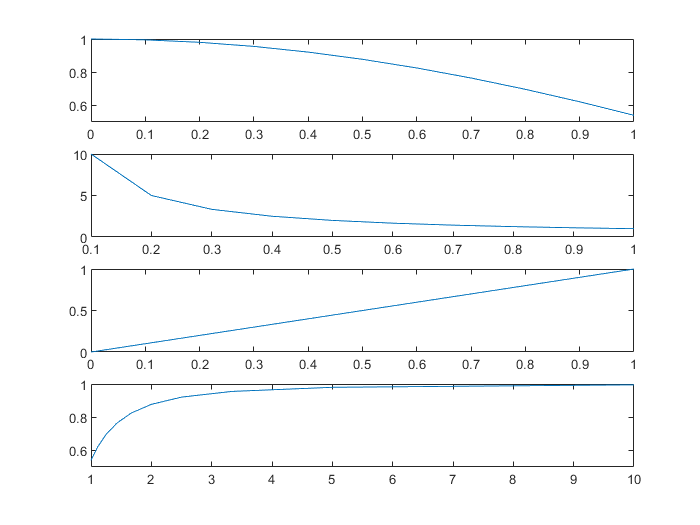

z=1./t;
figure
subplot(4,1,1)
plot(t,y)

subplot(4,1,2)
plot(t,z)

subplot(4,1,3)
plot(t,t)

subplot(4,1,4)
plot(z,y)

## Importing/Exporting Data

Load & Save

% Store data into an excel sheet
filename = 'file.xlsx';
A = {'muhammad','arslan';8,6};
sheet = 1;
xlRange = 'A1';
xlswrite(filename,A,sheet,xlRange)

% Copy data from an excel sheet 
x = xlsread("file.xlsx");

### Write matrix A to data.xls and fit elements of A in A2:C4

filename = 'data.xlsx'

filename = 'data.xlsx'

A = rand(4);
sheet = 1;
xlRange = 'A2:C4'

xlRange = 'A2:C4'


xlswrite(filename,A,sheet,xlRange)

#### Writing onto a text file 

x = xlsread("data.xlsx")

x =     0.6160    0.5853    0.7572
    0.4733    0.5497    0.7537
    0.3517    0.9172    0.3804


x = num2str(x)

x = 3×31 char array
    '0.61604     0.58526      0.7572'
    '0.47329     0.54972     0.75373'
    '0.35166     0.91719     0.38045'


fid = fopen('mystuff.txt','w')

fid = 3

count = fwrite(fid, x);

fclose(fid);

#### Read from a text file

fid = fopen('mystuff.txt','r')

fid = 4

fclose(fid);

# Lab 28_Sep_2023

Revision Subplot & File Manipulation 

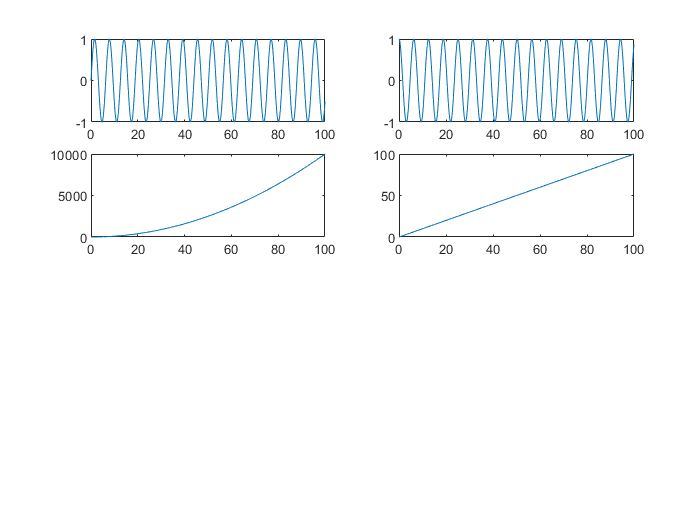

clear all, close all
x = 0:0.1:100;
y = sin(x);
z = cos(x);
w = x.^2;
v = x;

subplot(4,2,1)
plot(x,y)
subplot(4,2,2)
plot(x,z)
subplot(4,2,3)
plot(x,w)
subplot(4,2,4)
plot(x,v)

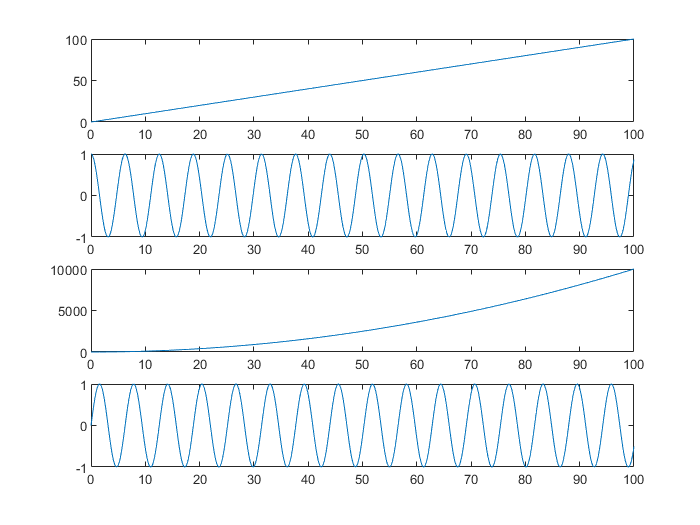

figure
subplot(4,1,1)
plot(x,v)
subplot(4,1,2)
plot(x,z)
subplot(4,1,3)
plot(x,w)
subplot(4,1,4)
plot(x,y)

%% File Manuplation
% Store data from xlsx into a variable
% xl_rd = xlsread('heart.xlsx')
%%
% 
A = rand(3);
xl_wt = xlswrite('testdata.xlsx', A);
% In Matlab Desktop Version this xlswrite will create xls file
% But Online version it'll create csv 
% range will show error inside the cell if not present
A = [4 5 5 5; 3 5 2 6; 2 5 2 5];
xl_wt = xlswrite('data1.xls', A, 'A2:C4');
%%
% Assignmet Practice
b = linspace(1,20,25)

b =     1.0000    1.7917    2.5833    3.3750    4.1667    4.9583    5.7500    6.5417    7.3333    8.1250    8.9167    9.7083   10.5000   11.2917   12.0833   12.8750   13.6667   14.4583   15.2500   16.0417   16.8333   17.6250   18.4167   19.2083   20.0000


xl_wt = xlswrite('data2.xls', b, 'b4:b7')

xl_wt = logical
   1



x_rd = xlsread('data2.xls'); disp(x_rd)

     1
     1
     1
     1



# Lab 5_Oct_2023 

#### Functions

h = @ones;
a = h()

a = 1

#### Function with one input

% function [m,s] = stat(x)
%  n = length(x);
%  m = sum(x)/n;
%  s = sqrt(sum((x-m).^2/n));
% end

% values = [12.7, 45.4, 98.9, 26.6, 53.1];
% [ave,stdev] = stat(values)


#### Function with four inputs

% function y = computeAverage(x1,x2,x3,x4)
% y = (x1+x2+x3+x4)/4;
% end

%% Computation

% f = computeAverage(2,3,6,7)

#### Ploting of a funciton

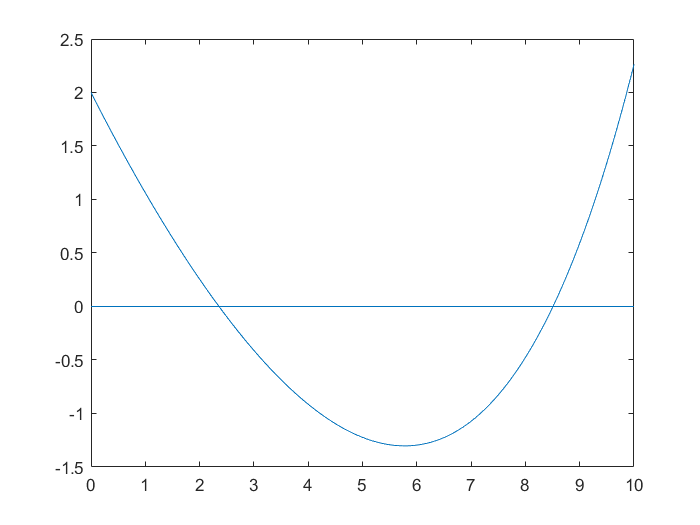

clc; clear all; close all;
f = @(x) 2*cosh(x/4)-x;
% a=0;
% b=6;
% tol=10e-6;
x = linspace(0,10,1000);
figure(1)
plot(x, f(x));
hold on
line([0 10], [0 0])

hold off

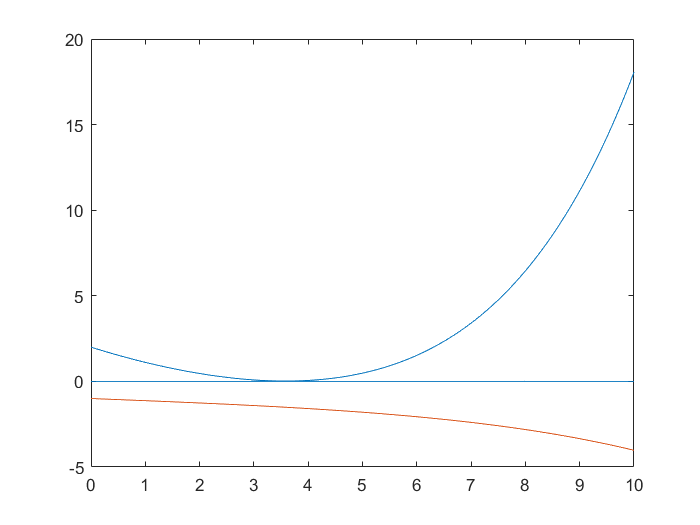


% 2.figure 2
clc; clear all; close all;
f = @(x) 2.*cosh(x/3)-x;
df= @(x) (-0.5).*sinh(x/4)-1;
x = linspace(0,10,1000);

figure(2)
plot(x, f(x),x,df(x));
hold on
line([0 10], [0 0])
hold off

#### Functions for sum of natural numbers

    Sum of Arithmetic Series (common difference) 

• “S” is the sum of the arithmetic sequence, 

• “a” as the first term, 

• “d” the common difference between the terms, 

• “n” is the total number of terms in the sequence and 


% function sum_arithmetic_series(n,a,d)
%  S = n/2*(2*a+(n-1)*d)
% end

• “L” is the last term of the sequence.

% function last_term(n,a,L)
%  S = n/2*(a+L)
% end


#### Sum of natural numbers (n) 

Save this inside the working dir 

Save this at the end of you script file

% function x = sum1(n)
% x = n*(n+1)/2;
% end

% function [t, x, y, z] = lorenz_odes45(tspan, x0, y0, z0)
% % lorenz_odes45: Solves the Lorenz equation using the odes45 method.
% 
% % Inputs:
% % tspan: The time span over which to solve the equation.
% % x0, y0, z0: The initial conditions.
% 
% % Outputs:
% % t: A vector of time points.
% % x, y, z: Vectors of the solutions.
% 
% % Define the Lorenz function.
% lorenz = @(t, y) [y(2) - y(1); y(1) - y(2) - y(1) * y(3); y(1) * y(2) - y(3)];
% 
% % Solve the equation using odes45.
% [t, y] = odes45(lorenz, tspan, [x0; y0; z0]);
% 
% % Extract the solutions for x, y, and z.
% x = y(:, 1);
% y = y(:, 2);
% z = y(:, 3);
% end

# Assignment 01

### Solving Odinary Differential Equation

Eqn = 'Dy=x*y^2+y'

Eqn = 'Dy=x*y^2+y'

Init='y(0)=1';
x = dsolve(Eqn,Init,'x')

$$x = -\frac{1}{x-1}$$

# Manipulation with txt File 

### Writing onto a txt file 

% fprintf% for reading txt file 
% Analyze the text file manipulation
x = 100*rand(8,1);
fileID = fopen('nums1.txt','w');
fprintf(fileID,'%4.4f\n',x);
fclose(fileID);

To create a new file 

fid = fopen('Asgn_01.txt','w')

fid = 8

fclose(fid);

To delete a text file 

% delete('Asgn_01.txt')
% force_delete('Asgn_01.txt')

To rename a text file 

% movefile('Asgn_01.txt', 'Asgn.txt');

To store data inside the text file

data = 'My name is Arslan'

data = 'My name is Arslan'


fid = fopen('Asgn_01.txt', 'w');
fwrite(fid, data);
fclose(fid);

 `fprintf` functions to read and write formatted data to a text file

data in the cell array `data` to a text file

fid = fopen('new_file.txt', 'w');
fprintf(fid, '%s %s\n', data);
fclose(fid);

# Quiz_01

### Sum of n_terms

Q: Write a snippet 'for' loop for taking sum of n terms using matlab language

% Prompt the user for the number of terms
n = input('Enter the number of terms: ');
% Initialize the sum
sum = 0;
% Iterate through the terms and add them to the sum
for i = 1:n
 sum = sum + i;
end
% Display the sum
disp(['The sum of the first ' n ' terms is ' num2str(sum) '.'])

% function x = sum0(n)
% % """Calculates the sum of the first n terms.
% % Args:
% % n: The number of terms.
% % Returns:
% % The sum of the first n terms.
% % """
%  x = 0;
%  for i = 1:n
%  x = x + i;
%  end
% end

% sum0(15)

# Lab 12_Oct_2023

### Solve the second & higher order odes and plot the solution

    
$$y''+8y'+2y = cos(x) 

\\
\\ y(0)=0\\ y'(0)=1$$


clear all, close all
Eqn2 = 'D2y + 8*Dy + 2*y = cos(x)'

Eqn2 = 'D2y + 8*Dy + 2*y = cos(x)'

Inits = "y(0) = 0, y'(0) = 1" % how to put initial condition with y'(0) = 1

Inits = "y(0) = 0, y'(0) = 1"

y = dsolve(Eqn2, Inits, 'x')

$$y = \begin{array}{l} \frac{\sqrt{14}\,\sigma_{2}\,\left(7\,\sqrt{14}-27\right)}{28\,\sigma_{3}}-\frac{\sqrt{14}\,{\mathrm{e}}^{4\,x+\sqrt{14}\,x}\,\sigma_{1}\,\left(\sin\left(x\right)+\cos\left(x\right)\,\left(\sqrt{14}+4\right)\right)}{28\,\left({\left(\sqrt{14}+4\right)}^{2}+1\right)}+\frac{\sqrt{14}\,{\mathrm{e}}^{4\,x-\sqrt{14}\,x}\,\sigma_{2}\,\left(\sin\left(x\right)-\cos\left(x\right)\,\left(\sqrt{14}-4\right)\right)}{28\,\left({\left(\sqrt{14}-4\right)}^{2}+1\right)}+\frac{\sqrt{14}\,\sigma_{1}\,\left(393\,\sqrt{14}-1531\right)}{28\,{\sigma_{3}}^{2}\,\left(8\,\sqrt{14}+31\right)}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-x\,\left(\sqrt{14}+4\right)}\\ \sigma_{2}={\mathrm{e}}^{x\,\left(\sqrt{14}-4\right)}\\ \sigma_{3}=8\,\sqrt{14}-31 \end{array}$$

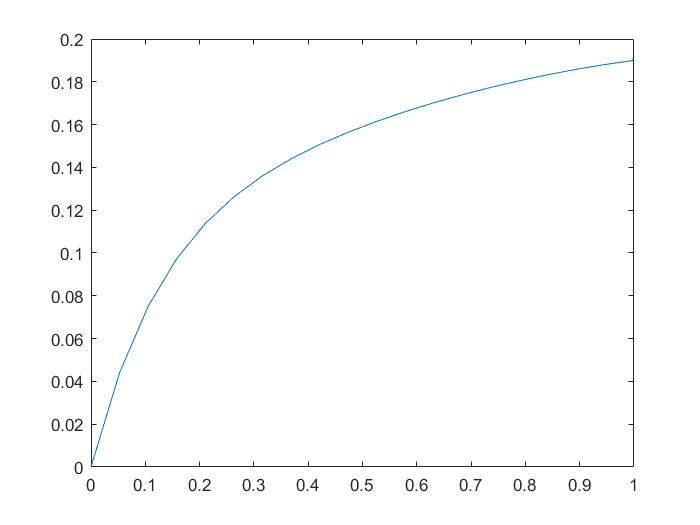


x = linspace(0,1,20);
z = eval(vectorize(y));
plot(x, z)

# Lab 19_Oct_2023

### Solve the differential equation


$$\frac{\textrm{dx}}{\textrm{dt}}=-r\;x$$


Method_1

dsolve('Dx=-r*x','t')

$$ans = C_{1}\,{\mathrm{e}}^{-r\,t}$$


$$\frac{\textrm{dy}}{\textrm{dx}}=x\;y$$


dsolve('Dy=x*y','x')

$$ans = C_{1}\,{\mathrm{e}}^{\frac{x^{2}}{2}}$$

Method_2

Eqn1 = 'Dy = x*y';
y = dsolve(Eqn1,'x')

$$y = C_{1}\,{\mathrm{e}}^{\frac{x^{2}}{2}}$$

Consider the initial value problem


$$\frac{\textrm{dy}}{\textrm{dx}}=\textrm{xy},y\left(1\right)=1$$


M_1


Eqn1 = 'Dy = x*y';
y = dsolve(Eqn1, 'y(1)=1', 'x')

$$y = {\mathrm{e}}^{-\frac{1}{2}}\,{\mathrm{e}}^{\frac{x^{2}}{2}}$$

M_2

clear all, close all
Eqn1 = 'Dy = x*y';
Init = 'y(1) = 1'

Init = 'y(1) = 1'

y = dsolve(Eqn1, Init, 'x')

$$y = {\mathrm{e}}^{-\frac{1}{2}}\,{\mathrm{e}}^{\frac{x^{2}}{2}}$$

Plot

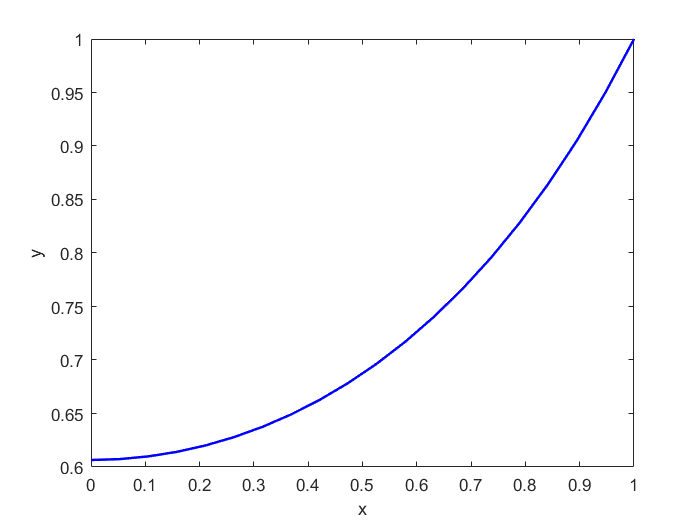

x = linspace(0,1,20);
z = eval(vectorize(y));
plot(x,z, 'b','linewidth',1.5)
xlabel ('x')
ylabel ('y')

## System of Multiple Odenary Differential Equations

### Analytical / Explicit Solution


$$dx/dt = x + 2y - z
$$



$$dy/dt = x + z$$



$$ dz/dt = 4x -4y +5z$$


clear all, close all
[x, y, z] = dsolve('Dx = x + 2*y - z',... %3dots show continuity
    'Dy = x + z', 'Dz = 4*x -4*y + 5*z', 't')

$$x = -\frac{C_{1}\,{\mathrm{e}}^{t}}{2}-\frac{C_{2}\,{\mathrm{e}}^{2\,t}}{2}-\frac{C_{3}\,{\mathrm{e}}^{3\,t}}{4}$$

$$y = \frac{C_{1}\,{\mathrm{e}}^{t}}{2}+\frac{C_{2}\,{\mathrm{e}}^{2\,t}}{4}+\frac{C_{3}\,{\mathrm{e}}^{3\,t}}{4}$$

$$z = C_{1}\,{\mathrm{e}}^{t}+C_{2}\,{\mathrm{e}}^{2\,t}+C_{3}\,{\mathrm{e}}^{3\,t}$$

Solve it using initial conditon

    
$$x(0) = 1 \\ y(0)=2 \\ z(0) = 3$$
 

A = 'Dx = x + 2*y - z'

A = 'Dx = x + 2*y - z'

B = 'Dy = x + z'

B = 'Dy = x + z'

C = 'Dz = 4*x -4*y + 5*z'

C = 'Dz = 4*x -4*y + 5*z'


Inits = 'x(0)=1, y(0)=2, z(0)=3'

Inits = 'x(0)=1, y(0)=2, z(0)=3'


[x, y, z] = dsolve(A, B, C, Inits, 't')

$$x = 6\,{\mathrm{e}}^{2\,t}-\frac{5\,{\mathrm{e}}^{3\,t}}{2}-\frac{5\,{\mathrm{e}}^{t}}{2}$$

$$y = \frac{5\,{\mathrm{e}}^{3\,t}}{2}-3\,{\mathrm{e}}^{2\,t}+\frac{5\,{\mathrm{e}}^{t}}{2}$$

$$z = 10\,{\mathrm{e}}^{3\,t}-12\,{\mathrm{e}}^{2\,t}+5\,{\mathrm{e}}^{t}$$

Finally plot the solution

t = linspace(0,0.5,25);
xx = eval(vectorize(x))

xx =     1.0000    1.0414    1.0822    1.1221    1.1608    1.1982    1.2338    1.2674    1.2985    1.3267    1.3517    1.3729    1.3898    1.4017    1.4082    1.4084    1.4017    1.3872    1.3640    1.3312    1.2878    1.2325    1.1644    1.0819    0.9837


yy = eval(vectorize(y))

yy =     2.0000    2.0862    2.1785    2.2774    2.3832    2.4967    2.6183    2.7486    2.8884    3.0382    3.1990    3.3714    3.5564    3.7549    3.9678    4.1963    4.4415    4.7047    4.9870    5.2900    5.6152    5.9641    6.3385    6.7402    7.1712


zz = eval(vectorize(z))

zz =     3.0000    3.2396    3.5014    3.7870    4.0984    4.4378    4.8074    5.2094    5.6467    6.1218    6.6378    7.1979    7.8055    8.4642    9.1780    9.9511   10.7881   11.6937   12.6731   13.7320   14.8762   16.1122   17.4467   18.8870   20.4411


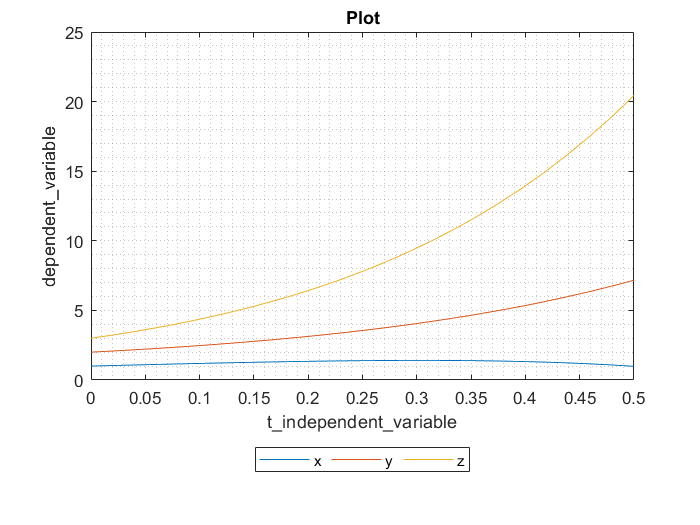

plot(t, xx, t, yy, t,zz)

title Plot
xlabel t\_independent\_variable
ylabel dependent\_variable
legend x y z Location bestoutside Orientation horizontal
grid minor
xlim('auto')
ylim('auto')

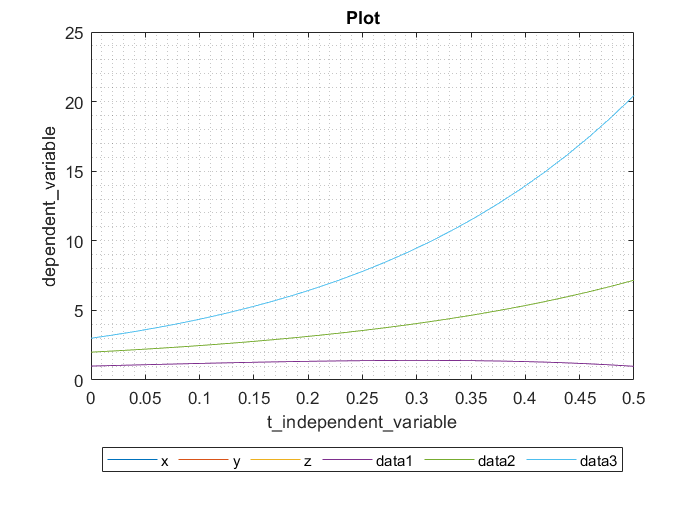


hold on 
plot(t,xx);
plot(t,yy);
plot(t,zz);
hold off

% Exact_Solution: Maple/Mathematica
% Numerical_Solution: Matlab
% * Newton Raphson Method - 2nd Order accurate

## 1st order numerical solutions


$$dy/dx = xy^2+y\\y(0)= 1$$


% y' = f(x,y)
f = @(x,y) x*y^2 + y % Give space b/w fun handle and expression

f = function_handle with value:
    @(x,y)x*y^2+y



[x,y] = ode45(f,[0 0.5],1)

x =          0
    0.0125
    0.0250
    0.0375
    0.0500
    0.0625
    0.0750
    0.0875
    0.1000
    0.1125


y =     1.0000
    1.0127
    1.0256
    1.0390
    1.0526
    1.0667
    1.0811
    1.0959
    1.1111
    1.1268


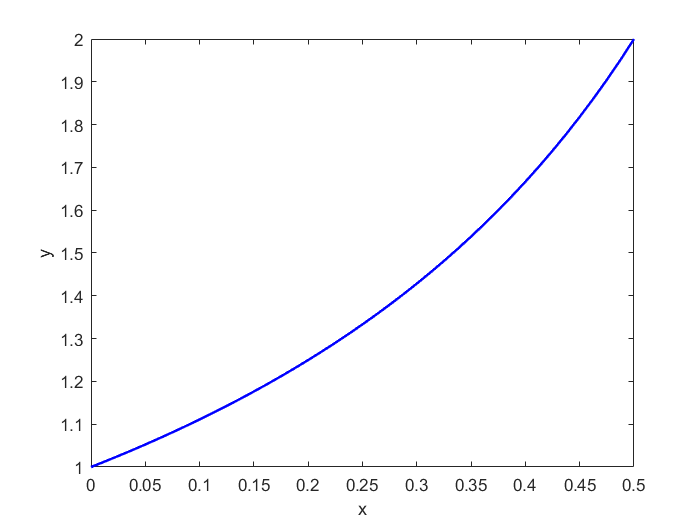

% Eular Method
% Runge Kuta Method More accurate for approximation | iteration
% RK2_ode23 | RK4_ode45 | ode113

plot(x,y,'b','linewidth',1.5)

xlabel('x')
ylabel('y')

[l,m] = ode23(f,[0 0.5],1)

l =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


m =     1.0000
    1.0526
    1.1111
    1.1765
    1.2500
    1.3333
    1.4286
    1.5384
    1.6666
    1.8181


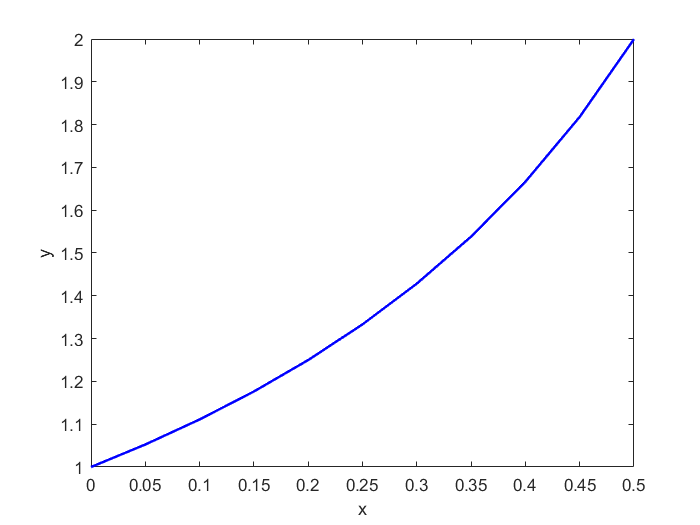


plot(l,m,'b','linewidth',1.5)

xlabel x
ylabel y

[n,o] = ode23(f,[0:0.1:0.5],1)

n =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000


o =     1.0000
    1.1111
    1.2500
    1.4286
    1.6666
    1.9999


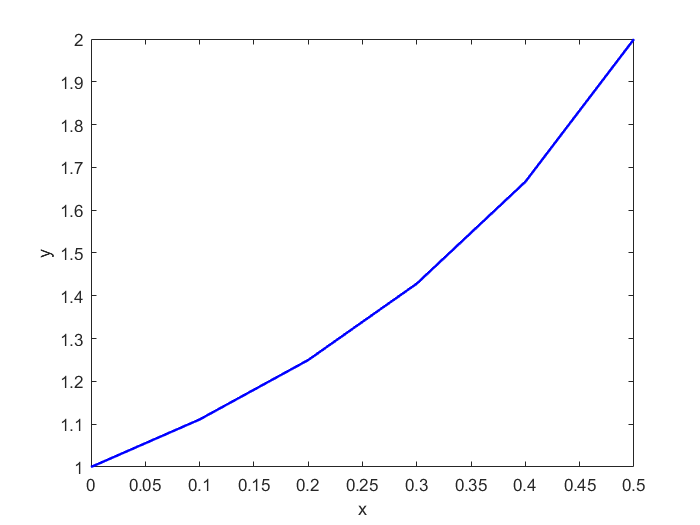

plot(n,o,'b','linewidth',1.5)
xlabel x
ylabel y

Alternate Method 

## First order equations with (Function) M-File

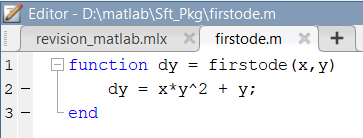

% function dy = firstode(x,y)
% dy = x*y^2 + y;
% end

% Call the function
xspan = [0 0.5];
y0 = 1;
[x,y] = ode45(@firstode,xspan,y0)

x =          0
    0.0125
    0.0250
    0.0375
    0.0500
    0.0625
    0.0750
    0.0875
    0.1000
    0.1125


y =     1.0000
    1.0127
    1.0256
    1.0390
    1.0526
    1.0667
    1.0811
    1.0959
    1.1111
    1.1268


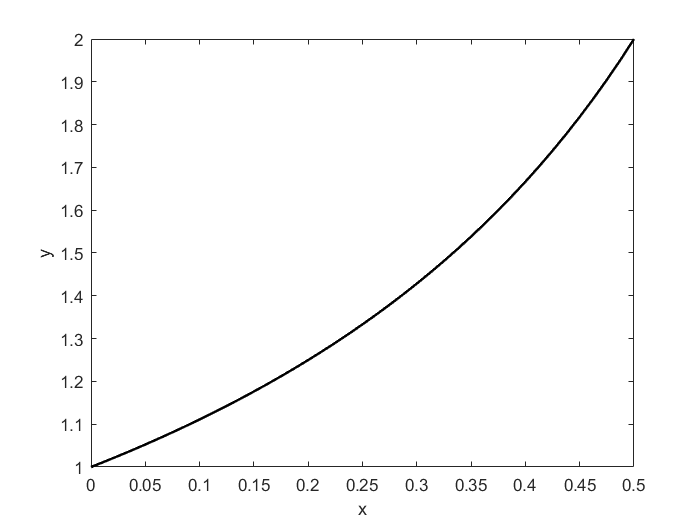


plot(x,y,'k','linewidth',1.5)
xlabel x
ylabel y

# Lab 26_Oct_2023

## Example: Solve the system of Lorenz equations 

dx/dt = $\sigma$(y - x) 

dy/dt = $\rho$x - y - xz 

dz/dt = xy - $\beta$z 

Take ,


$$\sigma \;=10,\beta =\frac{8}{3}\;,\rho =28$$



$$x\left(0\right)=-8,y=8,z\left(0\right)=27$$


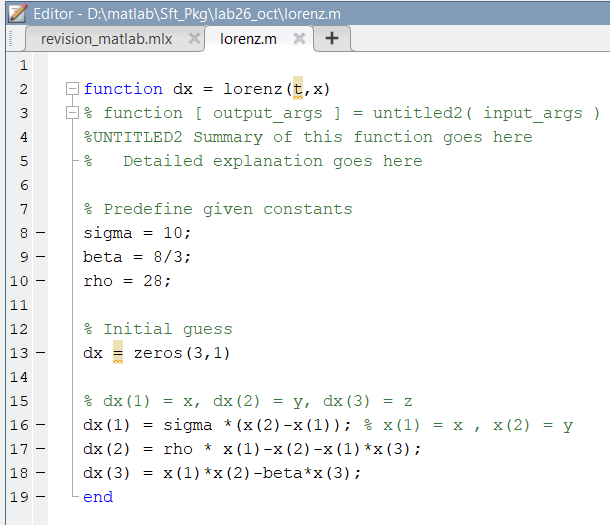

% function dx = lorenz(t,x)
% sigma = 10;
% beta = 8/3;
% rho = 28;
% dx = zero(3,1)
% dx(1) = sigma *(x(2)-x(1)); % x(1) = x , x(2) = y
% dx(2) = rho * x(1)-x(2)-x(1)*x(3);
% dx(3) = x(1)*x(2)-beta*x(3);
% end

% X = (x, y, z)
% dX = (dx, dy, dz)

x0 = [-8 8 27];
tspan = [0,20]

tspan =      0    20


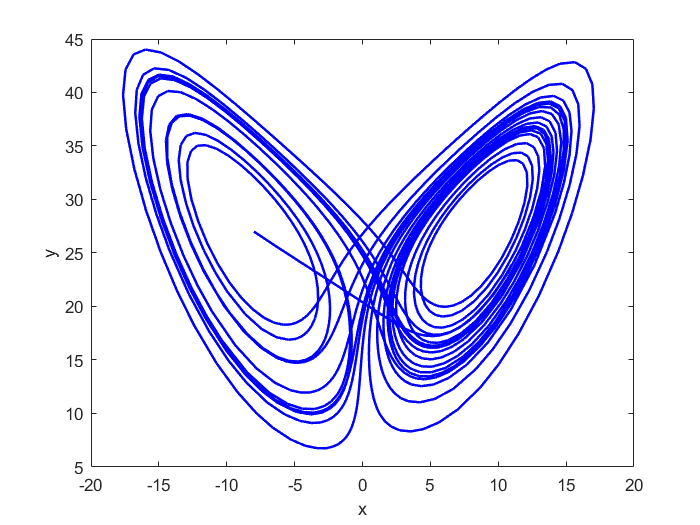


[t, x] = ode45(@lorenz, tspan, x0)

plot(x(:,1),x(:,3), 'b', 'linewidth',1.5)
xlabel ('x')
ylabel ('y')

### Subplotting Lorenz solution

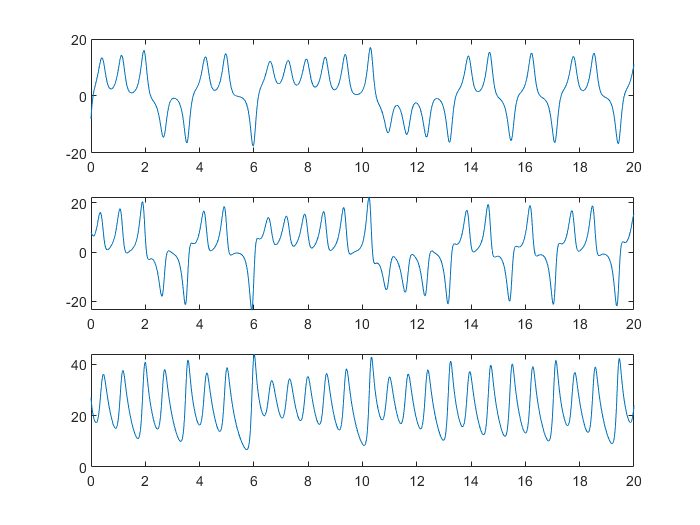

subplot (3,1,1)
plot(t,x(:,1))
subplot (3,1,2)
plot(t,x(:,2))
subplot (3,1,3)
plot(t,x(:,3))

# Assignment_02

Question: 

dx/dt = $\sigma$(y - x) 

dy/dt = $\rho$x - y - xz 

dz/dt = xy - $\beta$z 

Initial conditions,


$$x\left(0\right)=-8,y\left(0\right)=8,z\left(0\right)=27$$


instead of dx vector use dx, dy, dz and Solve this system of Lorenz Equation

# Quiz_02

Statement:


$${y^{\prime } }^{\prime } +8y^{\prime } +2y=\cos \left(x\right)$$


Solve using command ode45 with initial conditions,


$$y^{\prime } \left(0\right)=0,\;y\left(0\right)=1$$



$$\textrm{xspan}=\left\lbrack 0,1\right\rbrack$$


Share Screenshorts (cmd, plot, mlx)

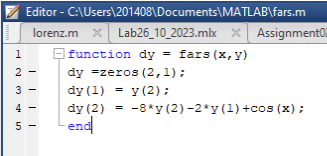

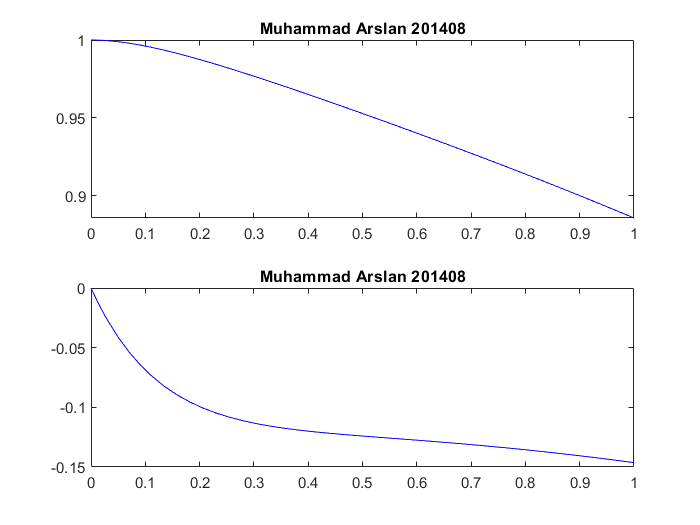

% function dy = fars(x,y)
% dy =zeros(2,1);
% dy(1) = y(2);
% dy(2) = -8*y(2)-2*y(1)+cos(x);
% end

xspan=[0 1];
y0=[1,0];
[x,y]=ode45(@fars,xspan,y0);
plot(y(:,1),y(:,2),'b')
subplot(2,1,1)
plot(x,y(:,1),'b')
title ('Muhammad Arslan 201408');
subplot(2,1,2)
plot(x,y(:,2),'b')
title ('Muhammad Arslan 201408');